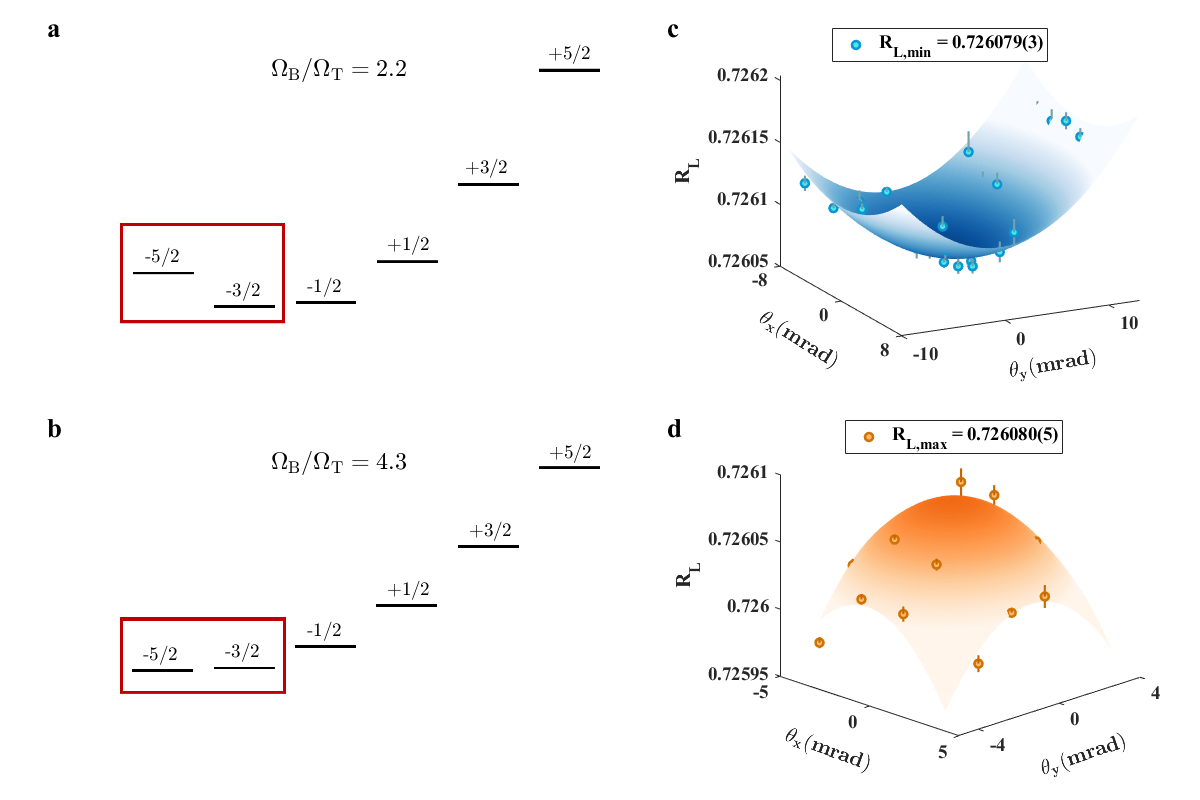


% Fig. 2 %

clear all;
close all;

loadFile = {'E:\Comagnetometer_Pub\Fig2\BT2_2.png',...
    'E:\Comagnetometer_Pub\Fig2\BT4_3.png',...
    'E:\Comagnetometer_Pub\Fig2\RvsD50.fig',...
    'E:\Comagnetometer_Pub\Fig2\RvsD100.fig'};

img1 = imread(loadFile{1});

img2 = imread(loadFile{2});

img3 = openfig(loadFile{3});
ax3 = img3.Children(end);
ax_c3 = ax3.Children;

img4 = openfig(loadFile{4});
ax4 = img4.Children(end);
ax_c4 = ax4.Children;


f1 = figure;
%tiledlayout(20,20,'TileSpacing','tight','Padding','tight');

% (a) %
a1 = axes('Position',[0.1 0.58 0.4 0.35]);
imshow(img1);

annotation(f1,'textbox',...
    [0.4510 0.9138 0.0415 0.0375],'String','+5/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation(f1,'textbox',...
    [0.3818 0.7712 0.0415 0.0375],'String','+3/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation(f1,'textbox',...
    [0.3168 0.6750 0.0415 0.0375],'String','+1/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation(f1,'textbox',...
    [0.2502 0.6225 0.0415 0.0375],'String','-1/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation(f1,'textbox',...
    [0.1827 0.6175 0.0415 0.0375],'String','-3/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
annotation(f1,'textbox',...
    [0.1152 0.6600 0.0415 0.0375],'String','-5/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');
% 创建 textbox
annotation(f1,'textbox',...
    [0.22 0.8925 0.1248 0.0425],...
    'String','$\Omega_{\rm B}/\Omega_{\rm T}=2.2$',...
    'LineWidth',1,...
    'Interpreter','latex',...
    'FontWeight','bold',...
    'FontSize',18,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'FaceAlpha',0,...
    'EdgeColor','none');

not1 = annotation(f1,'textbox',...
    [0.034,0.94,0.05,0.05],...
    'String','a',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');



% (b) %
a2 = axes('Position',[0.1 0.1 0.4 0.35]);
imshow(img2);

annotation(f1,'textbox',...
    [0.4518 0.4150 0.0415 0.0375],'String','+5/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(f1,'textbox',...
    [0.3852 0.3174 0.0415 0.0375],'String','+3/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(f1,'textbox',...
    [0.3168 0.24375 0.0415 0.0375],'String','+1/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(f1,'textbox',...
    [0.2502 0.1925 0.0415 0.0375],'String','-1/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(f1,'textbox',...
    [0.1819 0.1662 0.0415 0.0375],'String','-3/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(f1,'textbox',...
    [0.1135 0.1625 0.0415 0.0375],'String','-5/2',...
    'Interpreter','latex',...
    'FontSize',14,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

annotation(f1,'textbox',...
    [0.22 0.4012 0.1248 0.0425],...
    'String','$\Omega_{\rm B}/\Omega_{\rm T}=4.3$',...
    'LineWidth',1,...
    'Interpreter','latex',...
    'FontWeight','bold',...
    'FontSize',18,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'FaceAlpha',0,...
    'EdgeColor','none');

not2 = annotation(f1,'textbox',...
    [0.034,0.44,0.05,0.05],...
    'String','b',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');


% (c) %
t3 = axes('Position',[0.65 0.58 0.3 0.37]);
copyobj(ax_c3,t3);

t3.Colormap = img3.Colormap;
clim([0.726075 0.72615]);

set(t3,'FontName',ax3.FontName,...
    'FontWeight',ax3.FontWeight,'FontSize',14);
xlim(t3,ax3.XLim);
ylim(t3,ax3.YLim);
xticks(t3,ax3.XTick);
yticks(t3,ax3.YTick);
set(t3,'XLabel',ax3.XLabel,'XTickLabel',ax3.XTickLabel);
set(t3,'YLabel',ax3.YLabel,'YTickLabel',ax3.YTickLabel);
set(t3,'ZLabel',ax3.ZLabel);
t3.XLabel.Position = [0.389475,-1.666097,0.726030];
t3.YLabel.Position = [0.886486,-0.843743,0.726026];

daspect auto;
view(t3,[62.904 22.309]);

legend('','R_{L,min} = 0.726079(3)', ...
    'Position',[0.70631,0.92250,0.15428,0.04250],'FontSize',14);

not3 = annotation(f1,'textbox',...
    [0.55,0.94,0.05,0.05],...
    'String','c',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');


% (d) %
t4 = axes('Position',[0.65 0.08 0.3 0.4]);
copyobj(ax_c4,t4);

t4.Colormap = img4.Colormap;
clim([0.726013 0.72612]);

set(t4,'FontName',ax4.FontName,...
    'FontWeight',ax4.FontWeight,'FontSize',14);
xlim(t4,ax4.XLim);
ylim(t4,ax4.YLim);
xticks(t4,ax4.XTick);
yticks(t4,ax4.YTick);
set(t4,'XLabel',ax4.XLabel,'XTickLabel',ax4.XTickLabel);
set(t4,'YLabel',ax4.YLabel,'YTickLabel',ax4.YTickLabel);
set(t4,'ZLabel',ax4.ZLabel);

t4.XLabel.Position = [0.840019,-2.630377,0.725929];
t4.YLabel.Position = [1.532233,-2.013320,0.725926];

daspect auto;
view(t4,[45.47989,22.57191]);

legend('','R_{L,max} = 0.726080(5)', ...
    'Position',[0.70631,0.4325,0.1780,0.0425],'FontSize',14);

not4 = annotation(f1,'textbox',...
    [0.55,0.44,0.05,0.05],...
    'String','d',...
    'FontWeight','bold',...
    'FontSize',20,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');


set(f1,'Position',[100 100 1200 800],'Visible','on');


% savefig(f1,'E:\Comagnetometer_Pub\Fig2\Fig2.fig');
% saveas(f1,'E:\Comagnetometer_Pub\Fig2\Fig2.png');
% hgexport(f1,'E:\Comagnetometer_Pub\Fig2\Fig2.eps');
% hgexport(f1,'E:\Comagnetometer_Pub\Fig\Fig2.eps');
% saveas(f1,'E:\Comagnetometer_Pub\Fig2\Fig2.svg');
% 
% save('E:\Comagnetometer_Pub\Fig2\Fig2.mat');
